## Defining Linear Model for Gyroscope Dynamics

clear
%% defining system parameters

% h - constant calculated based on the moment of inertia of the gyroscope rotor
% Jy - moment of inertia about the y-axis angle
% Jz - moment of inertia about the z-axis angle

syms h Jy Jz

% A and B matrices of linear model ( dx/dt = Ax + Bu )

A_syms = [0 0 -h/Jy 0;
     0 0 1 0;
     h/Jz 0 0 0;
     0 1 0 0];

B_syms = [1/Jy; 0; 0; 0];

A_fun = formula(A_syms);
B_fun = formula(B_syms);

h_val = 0.44;
Jy_val = 0.0039;
Jz_val = 0.0223;

A = subs(A_syms,{h,Jy,Jz},{h_val,Jy_val,Jz_val});
A = double(A);
B = subs(B_syms,{h,Jy,Jz},{h_val,Jy_val,Jz_val});
B = double(B);

% defining equilibrium state 

state_e = [0 0 0 0];

## Simulating Open Loop System

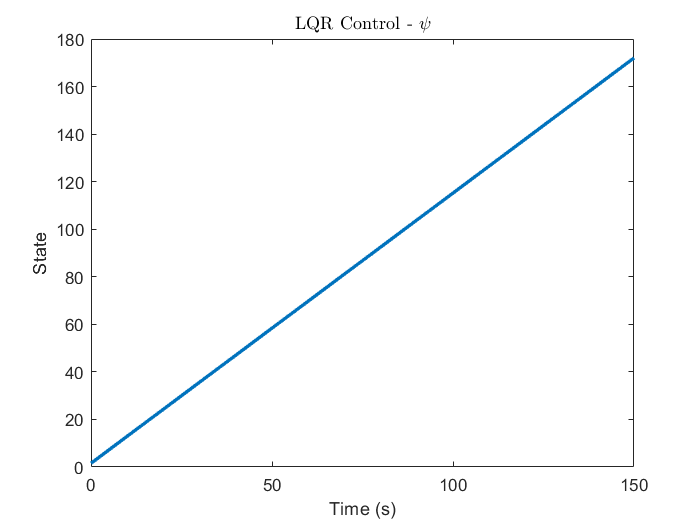

% specifiying initial state of system
state_initial = [0 pi/2 0 0];
% specifying time period and time steps for the simulation 
tspan=0:0.005:150;

[t,x] = ode45(@(t,x)(A*x+B*0.5),tspan,state_initial);

% plotting variation of state
figure
plot(t,x(:,2),'LineWidth',2)
hold on
title("LQR Control - $\psi$", 'interpreter','latex' )
% legend('$\dot{\theta}$','$\psi$', '$\dot{\psi}$', 'interpreter','latex' )
xlabel('Time (s)')
ylabel('State')
hold off

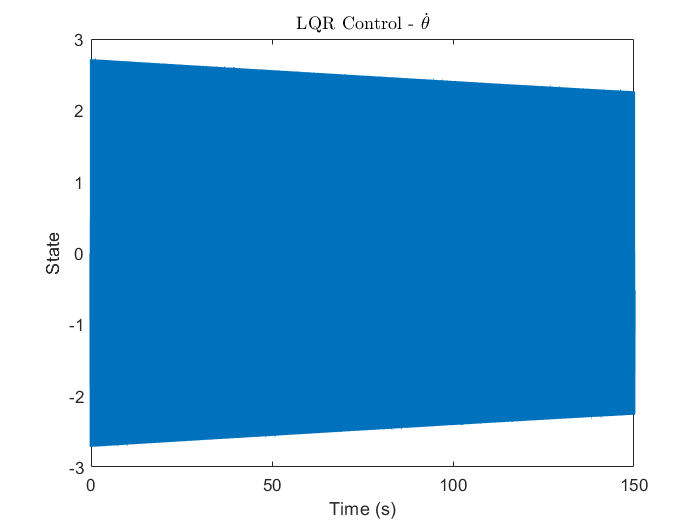

% plotting variation of state
figure
plot(t,x(:,1),'LineWidth',2)
hold on
title("LQR Control - $\dot{\theta}$", 'interpreter','latex' )
% legend('$\dot{\theta}$','$\psi$', '$\dot{\psi}$', 'interpreter','latex' )
xlabel('Time (s)')
ylabel('State')
hold off

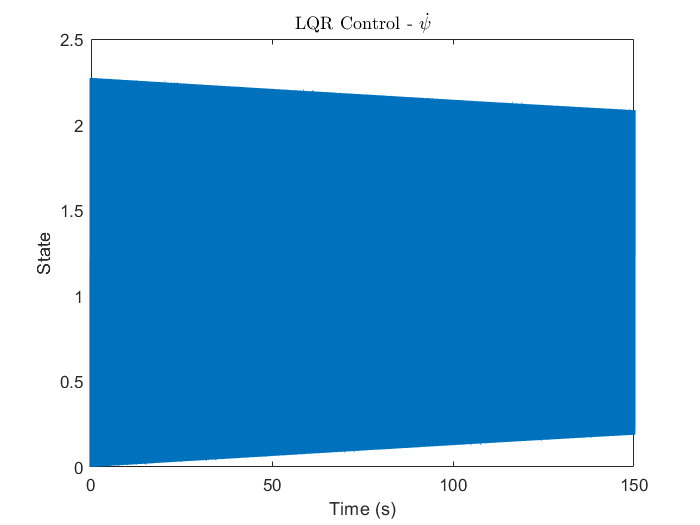


% plotting variation of state
figure
plot(t,x(:,3),'LineWidth',2)
hold on
title("LQR Control - $\dot{\psi}$", 'interpreter','latex' )
% legend('$\dot{\theta}$','$\psi$', '$\dot{\psi}$', 'interpreter','latex' )
xlabel('Time (s)')
ylabel('State')
hold off

## Obtaining LQR Controller Gains

% Q and R matrices for obtaining LQR controller gains 

Q = diag([2 16 0.01 0.0001]);
R = 5;

% Using the inbuilt Matlab Function to obtain LQR controller gains 

K_LQR = lqr(A,B,Q,R);


## Obtaining LQG Controller Gains

% Defining noise covariance matrices 

Qn = eye(4); 
Rn = 0.1;

% Using inbuilt MATLAB function to obtain LQG controller gains

QXU = blkdiag(Q,R);
QWV = blkdiag(Qn,Rn);
sys = ss(A,B,[0 1 0 0],0);
%[K,info] = lqg(sys,QXU,QWV);
%K_LQG = info.Kx;


## Simulating CLosed Loop Response with LQR Controller

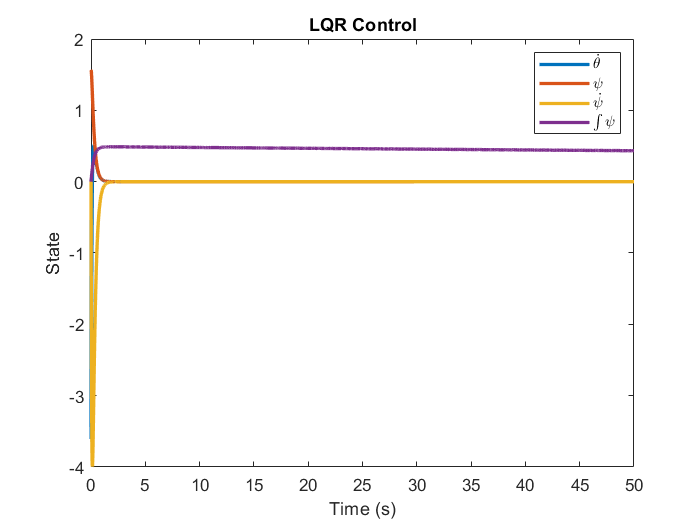

% specifiying initial state of system
state_initial = [0 pi/2 0 0];
% specifying time period and time steps for the simulation 
tspan=0:0.005:50;

% simulating the closed loop response
% a - state 
[t,a] = ode45(@(t,a)((A-B*K_LQR)*(a-state_e')),tspan,state_initial);

% plotting variation of state
figure
plot(t,a,'LineWidth',2)
hold on
title("LQR Control")
legend('$\dot{\theta}$','$\psi$', '$\dot{\psi}$', '$\int{\psi}$', 'interpreter','latex' )
xlabel('Time (s)')
ylabel('State')
hold off

## Simulating Closed Loop Response with LQG Controller

%[t,a] = ode45(@(t,a)(A*(a-state_e')-B*awgn(K_LQG*(a-state_e'),0)),tspan,state_initial);

% plotting variation of state
figure
plot(t,a,'LineWidth',2)
hold on
title("LQR Control")
legend('$\dot{\theta}$','$\psi$', '$\dot{\psi}$', '$\int{\psi}$', 'interpreter','latex' )
xlabel('Time (s)')
ylabel('State')
hold off

## Simulating for Varying Initial Conditions

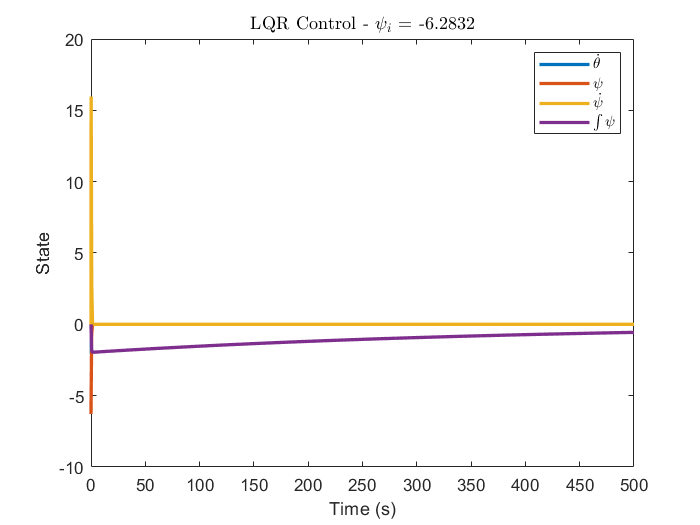

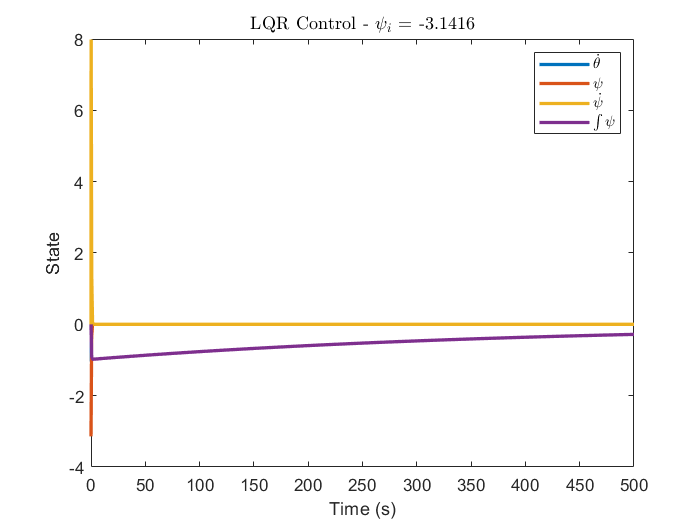

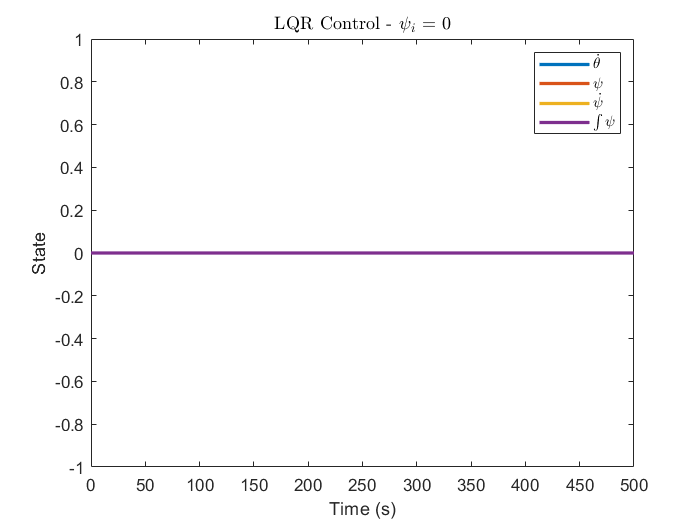

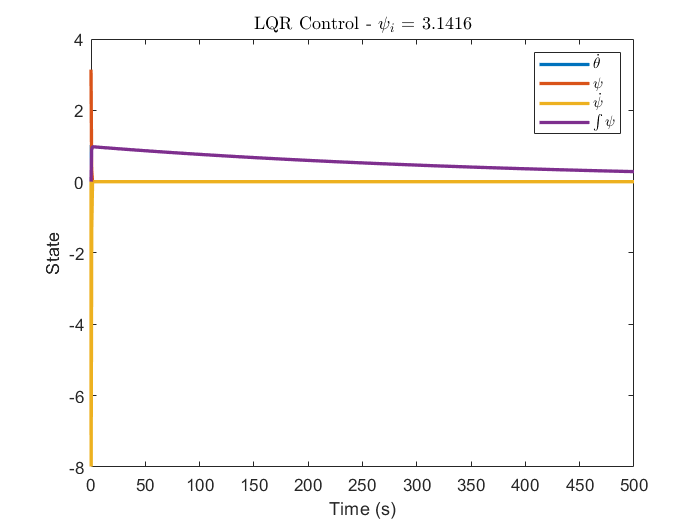

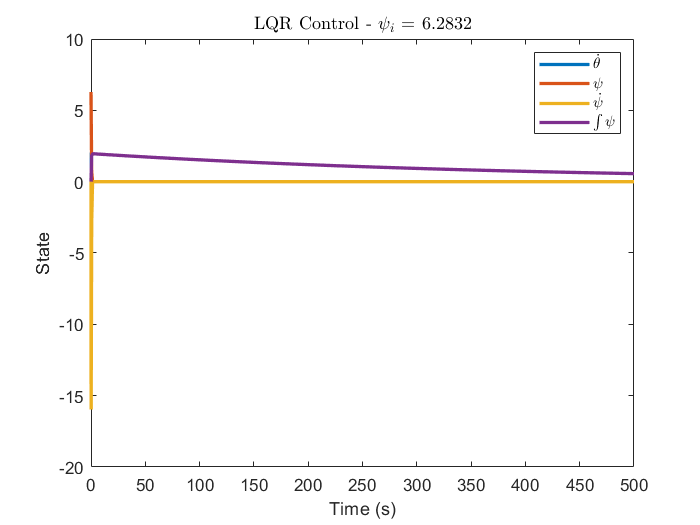

% specifying time period and time steps for the simulation 
data = zeros(4,11);
st = [0,0,0];
tspan=0:0.01:500;
i_max = 2;
for i = -i_max:1:i_max
    % specifiying initial state of system
    state_initial = [0 (2*pi/i_max)*i 0 0];
    
    % simulating the closed loop response
    % a - state 
    [t,a] = ode45(@(t,a)((A-B*K_LQR)*(a-state_e')),tspan,state_initial);
    
    u_data = -K_LQR*a'+ K_LQR*state_e';
    for n = 1:1:3
                b = settlingtime(a(:,n),t,4/5*tspan(end),'Tolerance',0.5);
                b = b(b>0);
                if isempty(b)
                    st(n) = 0;
                else
                    st(n) = b(1);
                end
    end
    data(i+i_max+1,:) = [max(u_data(1,:)),mean(u_data(1,:)),max(a(:,1)-state_e(1)),max(a(:,2)-state_e(2)),max(a(:,3)-state_e(3)),max(a(:,1)),max(a(:,2)),max(a(:,3)),st];
    
    
    % plotting variation of psi and theta
    hold on
    figure
    plot(t,a(:,1:4),'LineWidth',2)
    title("LQR Control - $\psi_i$ = " + state_initial(2), 'interpreter','latex' )
    legend('$\dot{\theta}$','$\psi$', '$\dot{\psi}$', '$\int{\psi}$', 'interpreter','latex' )
    xlabel('Time (s)')
    ylabel('State')
    hold off
    
end

## Simulating with Uncertainty in System Parameters

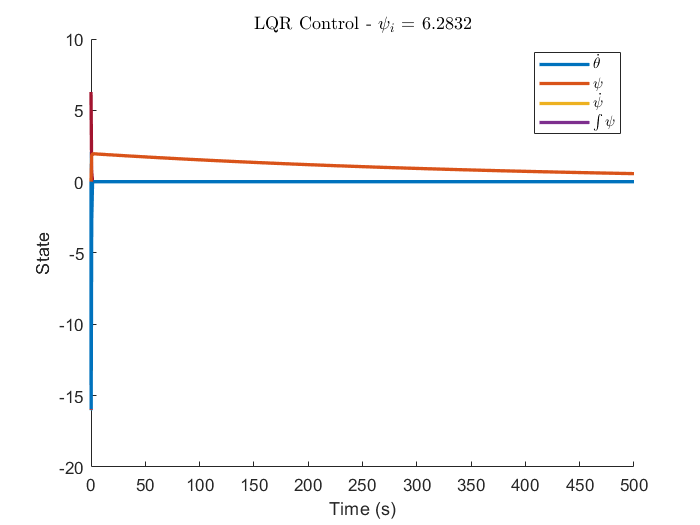

uncertainty = 10;
figure
hold on 
for var_i = -uncertainty:1:uncertainty
    for var_i0 = -uncertainty:1:uncertainty
        B_uncert=subs(B_fun,{h,Jy,Jz},{h_val,Jy_val*(1+var_i/100),Jz_val*(1+var_i0/100)});
        A_uncert=subs(A_fun,{h,Jy,Jz},{h_val,Jy_val*(1+var_i/100),Jz_val*(1+var_i0/100)});
        A=double(A_uncert);
        B=double(B_uncert);
        [t,a] = ode45(@(t,a)((A-B*K_LQR)*(a-state_e')),tspan,state_initial);
        plot(t,a,'LineWidth',2)
    end
end
title("LQR Control - $\psi_i$ = " + state_initial(2), 'interpreter','latex' )
legend('$\dot{\theta}$','$\psi$', '$\dot{\psi}$', '$\int{\psi}$', 'interpreter','latex' )
xlabel('Time (s)')
ylabel('State')
hold off